# Saving and Exporting Files & Figures

There are oftentimes multiple ways to accomplish a task in MATLAB. Of course, you can always write some code to complete your task programmatically. But what if you do not know the code needed to get your results? Try solving your problem with MATLAB's interactive tools, and use those tools to automatically generate the code you need in the future.

**PDF (vectorized)**

From one of your figure windows, choose what file format you want to save or export your figure as. 

To save your figure as a vector pdf - a file type that allows for near infinite resolution in a manageable file size, go to Save As > Export to > PDF and select "Vector" under Content type.

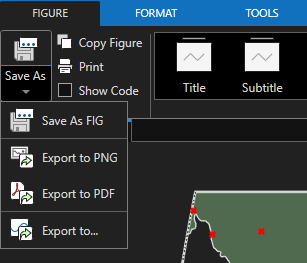

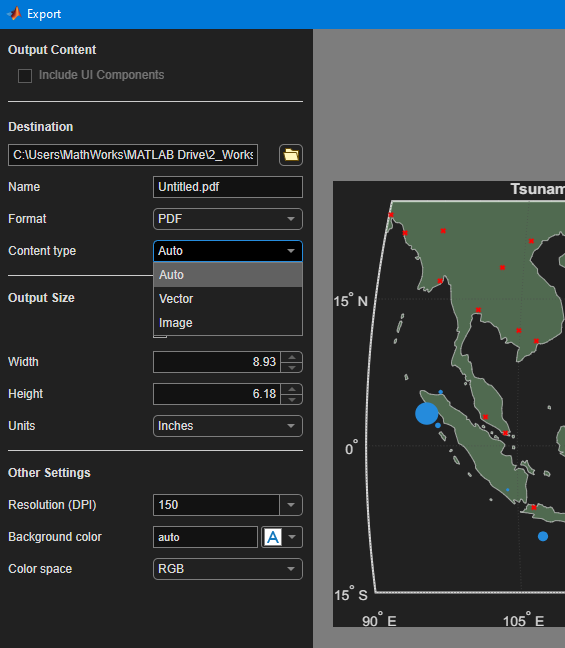

## **Exporting data in common Earth science file formats**

### **Shape Files**

We used `shaperead `to read shape file data into our workspace. Now, we can use [`shapewrite`](https://www.mathworks.com/help/map/ref/shapewrite.html?searchHighlight=shapewrite&s_tid=srchtitle_support_results_1_shapewrite) to export shape file data.

load("coastlines.mat")
shapeinfo("worldrivers.shp")

ans = struct with fields:
                     Filename: [3×96 char]
                    ShapeType: 'PolyLine'
                  BoundingBox: [2×2 double]
                  NumFeatures: 128
                   Attributes: [1×1 struct]
    CoordinateReferenceSystem: [1×1 geocrs]


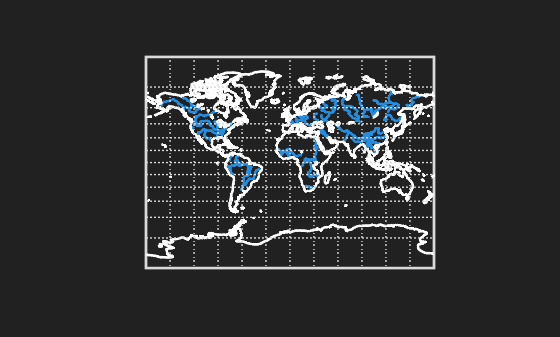

figure
axesm('MapProjection','miller','frame', 'on', 'grid', 'on')
axis off

geoshow(GT)
hold on
plotm(coastlat,coastlon,'w')



% The NumFeatures field indicates that the shapefile contains 609 features
% Import the shapefile as a geospatial table.

GT = readgeotable("worldrivers.shp");

rows = GT.Name == "";
noBlanksGT = GT(~rows,:);

% Export the geospatial table as a shapefile.
shapewrite(noBlanksGT,"worldrivers_no_blank.shp")

### NetCDF Files

#### Import

Just as we used `shaperead/write` for importing and saving .shp files, we can use functions such as `xlmread/write`, `ncread/write`, `geotiffread/write`, or `readgeoraster `for working with their respective file formats. Many file formats also have additional functions dedicated to extracting and manipulating the specific data that they commonly store. For full documentation on MATLAB-supported raster GIS and geospatial data files, [explore here](https://www.mathworks.com/help/map/file-import-and-export.html?s_tid=CRUX_lftnav).

Let's see how the Import Data task can help us again, this time with netCDF files.

% Create a structure to store imported netCDF data
mynetfile = struct();

filename = "C:\Users\MathWorks\Downloads\1820000_20180101to20181231.nc";

mynetfile.Variables(1).Name = "timeSeries";
mynetfile.Variables(1).Value = ncread(filename, "/timeSeries");

mynetfile.Variables(2).Name = "lat";
mynetfile.Variables(2).Value = ncread(filename, "/lat");

mynetfile.Variables(3).Name = "lon";
mynetfile.Variables(3).Value = ncread(filename, "/lon");

mynetfile.Variables(4).Name = "time";
mynetfile.Variables(4).Value = ncread(filename, "/time");

mynetfile.Variables(5).Name = "waterlevel_unassessed";
mynetfile.Variables(5).Value = ncread(filename, "/waterlevel_unassessed");

mynetfile.Variables(6).Name = "waterlevel_datum_altitude";
mynetfile.Variables(6).Value = ncread(filename, "/waterlevel_datum_altitude");

mynetfile.Variables(7).Name = "crs";
mynetfile.Variables(7).Value = ncread(filename, "/crs");

mynetfile.Variables(1).Attributes(1).Name = "long_name";
mynetfile.Variables(1).Attributes(1).Value = ncreadatt(filename, "/timeSeries", "long_name");

mynetfile.Variables(1).Attributes(2).Name = "cf_role";
mynetfile.Variables(1).Attributes(2).Value = ncreadatt(filename, "/timeSeries", "cf_role");

mynetfile.Variables(2).Attributes(1).Name = "long_name";
mynetfile.Variables(2).Attributes(1).Value = ncreadatt(filename, "/lat", "long_name");

mynetfile.Variables(2).Attributes(2).Name = "standard_name";
mynetfile.Variables(2).Attributes(2).Value = ncreadatt(filename, "/lat", "standard_name");

mynetfile.Variables(2).Attributes(3).Name = "units";
mynetfile.Variables(2).Attributes(3).Value = ncreadatt(filename, "/lat", "units");

mynetfile.Variables(2).Attributes(4).Name = "axis";
mynetfile.Variables(2).Attributes(4).Value = ncreadatt(filename, "/lat", "axis");

mynetfile.Variables(2).Attributes(5).Name = "valid_min";
mynetfile.Variables(2).Attributes(5).Value = ncreadatt(filename, "/lat", "valid_min");

mynetfile.Variables(2).Attributes(6).Name = "valid_max";
mynetfile.Variables(2).Attributes(6).Value = ncreadatt(filename, "/lat", "valid_max");

mynetfile.Variables(2).Attributes(7).Name = "ancillary_variables";
mynetfile.Variables(2).Attributes(7).Value = ncreadatt(filename, "/lat", "ancillary_variables");

mynetfile.Variables(2).Attributes(8).Name = "comment";
mynetfile.Variables(2).Attributes(8).Value = ncreadatt(filename, "/lat", "comment");

mynetfile.Variables(2).Attributes(9).Name = "sdn_parameter_urn";
mynetfile.Variables(2).Attributes(9).Value = ncreadatt(filename, "/lat", "sdn_parameter_urn");

mynetfile.Variables(2).Attributes(10).Name = "sdn_parameter_name";
mynetfile.Variables(2).Attributes(10).Value = ncreadatt(filename, "/lat", "sdn_parameter_name");

mynetfile.Variables(2).Attributes(11).Name = "sdn_uom_urn";
mynetfile.Variables(2).Attributes(11).Value = ncreadatt(filename, "/lat", "sdn_uom_urn");

mynetfile.Variables(2).Attributes(12).Name = "sdn_uom_name";
mynetfile.Variables(2).Attributes(12).Value = ncreadatt(filename, "/lat", "sdn_uom_name");

mynetfile.Variables(3).Attributes(1).Name = "long_name";
mynetfile.Variables(3).Attributes(1).Value = ncreadatt(filename, "/lon", "long_name");

mynetfile.Variables(3).Attributes(2).Name = "standard_name";
mynetfile.Variables(3).Attributes(2).Value = ncreadatt(filename, "/lon", "standard_name");

mynetfile.Variables(3).Attributes(3).Name = "units";
mynetfile.Variables(3).Attributes(3).Value = ncreadatt(filename, "/lon", "units");

mynetfile.Variables(3).Attributes(4).Name = "axis";
mynetfile.Variables(3).Attributes(4).Value = ncreadatt(filename, "/lon", "axis");

mynetfile.Variables(3).Attributes(5).Name = "valid_min";
mynetfile.Variables(3).Attributes(5).Value = ncreadatt(filename, "/lon", "valid_min");

mynetfile.Variables(3).Attributes(6).Name = "valid_max";
mynetfile.Variables(3).Attributes(6).Value = ncreadatt(filename, "/lon", "valid_max");

mynetfile.Variables(3).Attributes(7).Name = "ancillary_variables";
mynetfile.Variables(3).Attributes(7).Value = ncreadatt(filename, "/lon", "ancillary_variables");

mynetfile.Variables(3).Attributes(8).Name = "comment";
mynetfile.Variables(3).Attributes(8).Value = ncreadatt(filename, "/lon", "comment");

mynetfile.Variables(3).Attributes(9).Name = "sdn_parameter_urn";
mynetfile.Variables(3).Attributes(9).Value = ncreadatt(filename, "/lon", "sdn_parameter_urn");

mynetfile.Variables(3).Attributes(10).Name = "sdn_parameter_name";
mynetfile.Variables(3).Attributes(10).Value = ncreadatt(filename, "/lon", "sdn_parameter_name");

mynetfile.Variables(3).Attributes(11).Name = "sdn_uom_urn";
mynetfile.Variables(3).Attributes(11).Value = ncreadatt(filename, "/lon", "sdn_uom_urn");

mynetfile.Variables(3).Attributes(12).Name = "sdn_uom_name";
mynetfile.Variables(3).Attributes(12).Value = ncreadatt(filename, "/lon", "sdn_uom_name");

mynetfile.Variables(4).Attributes(1).Name = "long_name";
mynetfile.Variables(4).Attributes(1).Value = ncreadatt(filename, "/time", "long_name");

mynetfile.Variables(4).Attributes(2).Name = "standard_name";
mynetfile.Variables(4).Attributes(2).Value = ncreadatt(filename, "/time", "standard_name");

mynetfile.Variables(4).Attributes(3).Name = "units";
mynetfile.Variables(4).Attributes(3).Value = ncreadatt(filename, "/time", "units");

mynetfile.Variables(4).Attributes(4).Name = "calendar";
mynetfile.Variables(4).Attributes(4).Value = ncreadatt(filename, "/time", "calendar");

mynetfile.Variables(4).Attributes(5).Name = "axis";
mynetfile.Variables(4).Attributes(5).Value = ncreadatt(filename, "/time", "axis");

mynetfile.Variables(4).Attributes(6).Name = "ancillary_variables";
mynetfile.Variables(4).Attributes(6).Value = ncreadatt(filename, "/time", "ancillary_variables");

mynetfile.Variables(4).Attributes(7).Name = "comment";
mynetfile.Variables(4).Attributes(7).Value = ncreadatt(filename, "/time", "comment");

mynetfile.Variables(4).Attributes(8).Name = "sdn_parameter_urn";
mynetfile.Variables(4).Attributes(8).Value = ncreadatt(filename, "/time", "sdn_parameter_urn");

mynetfile.Variables(4).Attributes(9).Name = "sdn_parameter_name";
mynetfile.Variables(4).Attributes(9).Value = ncreadatt(filename, "/time", "sdn_parameter_name");

mynetfile.Variables(4).Attributes(10).Name = "sdn_uom_urn";
mynetfile.Variables(4).Attributes(10).Value = ncreadatt(filename, "/time", "sdn_uom_urn");

mynetfile.Variables(4).Attributes(11).Name = "sdn_uom_name";
mynetfile.Variables(4).Attributes(11).Value = ncreadatt(filename, "/time", "sdn_uom_name");

mynetfile.Variables(5).Attributes(1).Name = "_FillValue";
mynetfile.Variables(5).Attributes(1).Value = ncreadatt(filename, "/waterlevel_unassessed", "_FillValue");

mynetfile.Variables(5).Attributes(2).Name = "long_name";
mynetfile.Variables(5).Attributes(2).Value = ncreadatt(filename, "/waterlevel_unassessed", "long_name");

mynetfile.Variables(5).Attributes(3).Name = "standard_name";
mynetfile.Variables(5).Attributes(3).Value = ncreadatt(filename, "/waterlevel_unassessed", "standard_name");

mynetfile.Variables(5).Attributes(4).Name = "coverage_content_type";
mynetfile.Variables(5).Attributes(4).Value = ncreadatt(filename, "/waterlevel_unassessed", "coverage_content_type");

mynetfile.Variables(5).Attributes(5).Name = "ncei_name";
mynetfile.Variables(5).Attributes(5).Value = ncreadatt(filename, "/waterlevel_unassessed", "ncei_name");

mynetfile.Variables(5).Attributes(6).Name = "units";
mynetfile.Variables(5).Attributes(6).Value = ncreadatt(filename, "/waterlevel_unassessed", "units");

mynetfile.Variables(5).Attributes(7).Name = "scale_factor";
mynetfile.Variables(5).Attributes(7).Value = ncreadatt(filename, "/waterlevel_unassessed", "scale_factor");

mynetfile.Variables(5).Attributes(8).Name = "add_offset";
mynetfile.Variables(5).Attributes(8).Value = ncreadatt(filename, "/waterlevel_unassessed", "add_offset");

mynetfile.Variables(5).Attributes(9).Name = "valid_min";
mynetfile.Variables(5).Attributes(9).Value = ncreadatt(filename, "/waterlevel_unassessed", "valid_min");

mynetfile.Variables(5).Attributes(10).Name = "valid_max";
mynetfile.Variables(5).Attributes(10).Value = ncreadatt(filename, "/waterlevel_unassessed", "valid_max");

mynetfile.Variables(5).Attributes(11).Name = "coordinates";
mynetfile.Variables(5).Attributes(11).Value = ncreadatt(filename, "/waterlevel_unassessed", "coordinates");

mynetfile.Variables(5).Attributes(12).Name = "grid_mapping";
mynetfile.Variables(5).Attributes(12).Value = ncreadatt(filename, "/waterlevel_unassessed", "grid_mapping");

mynetfile.Variables(5).Attributes(13).Name = "source";
mynetfile.Variables(5).Attributes(13).Value = ncreadatt(filename, "/waterlevel_unassessed", "source");

mynetfile.Variables(5).Attributes(14).Name = "references";
mynetfile.Variables(5).Attributes(14).Value = ncreadatt(filename, "/waterlevel_unassessed", "references");

mynetfile.Variables(5).Attributes(15).Name = "cell_methods";
mynetfile.Variables(5).Attributes(15).Value = ncreadatt(filename, "/waterlevel_unassessed", "cell_methods");

mynetfile.Variables(5).Attributes(16).Name = "ancillary_variables";
mynetfile.Variables(5).Attributes(16).Value = ncreadatt(filename, "/waterlevel_unassessed", "ancillary_variables");

mynetfile.Variables(5).Attributes(17).Name = "platform";
mynetfile.Variables(5).Attributes(17).Value = ncreadatt(filename, "/waterlevel_unassessed", "platform");

mynetfile.Variables(5).Attributes(18).Name = "instrument";
mynetfile.Variables(5).Attributes(18).Value = ncreadatt(filename, "/waterlevel_unassessed", "instrument");

mynetfile.Variables(5).Attributes(19).Name = "comment";
mynetfile.Variables(5).Attributes(19).Value = ncreadatt(filename, "/waterlevel_unassessed", "comment");

mynetfile.Variables(5).Attributes(20).Name = "sdn_parameter_urn";
mynetfile.Variables(5).Attributes(20).Value = ncreadatt(filename, "/waterlevel_unassessed", "sdn_parameter_urn");

mynetfile.Variables(5).Attributes(21).Name = "sdn_parameter_name";
mynetfile.Variables(5).Attributes(21).Value = ncreadatt(filename, "/waterlevel_unassessed", "sdn_parameter_name");

mynetfile.Variables(5).Attributes(22).Name = "sdn_uom_urn";
mynetfile.Variables(5).Attributes(22).Value = ncreadatt(filename, "/waterlevel_unassessed", "sdn_uom_urn");

mynetfile.Variables(5).Attributes(23).Name = "sdn_uom_name";
mynetfile.Variables(5).Attributes(23).Value = ncreadatt(filename, "/waterlevel_unassessed", "sdn_uom_name");

mynetfile.Variables(6).Attributes(1).Name = "long_name";
mynetfile.Variables(6).Attributes(1).Value = ncreadatt(filename, "/waterlevel_datum_altitude", "long_name");

mynetfile.Variables(6).Attributes(2).Name = "standard_name";
mynetfile.Variables(6).Attributes(2).Value = ncreadatt(filename, "/waterlevel_datum_altitude", "standard_name");

mynetfile.Variables(6).Attributes(3).Name = "coverage_content_type";
mynetfile.Variables(6).Attributes(3).Value = ncreadatt(filename, "/waterlevel_datum_altitude", "coverage_content_type");

mynetfile.Variables(6).Attributes(4).Name = "units";
mynetfile.Variables(6).Attributes(4).Value = ncreadatt(filename, "/waterlevel_datum_altitude", "units");

mynetfile.Variables(6).Attributes(5).Name = "sdn_parameter_urn";
mynetfile.Variables(6).Attributes(5).Value = ncreadatt(filename, "/waterlevel_datum_altitude", "sdn_parameter_urn");

mynetfile.Variables(6).Attributes(6).Name = "sdn_parameter_name";
mynetfile.Variables(6).Attributes(6).Value = ncreadatt(filename, "/waterlevel_datum_altitude", "sdn_parameter_name");

mynetfile.Variables(6).Attributes(7).Name = "sdn_uom_urn";
mynetfile.Variables(6).Attributes(7).Value = ncreadatt(filename, "/waterlevel_datum_altitude", "sdn_uom_urn");

mynetfile.Variables(6).Attributes(8).Name = "sdn_uom_name";
mynetfile.Variables(6).Attributes(8).Value = ncreadatt(filename, "/waterlevel_datum_altitude", "sdn_uom_name");

mynetfile.Variables(7).Attributes(1).Name = "grid_mapping_name";
mynetfile.Variables(7).Attributes(1).Value = ncreadatt(filename, "/crs", "grid_mapping_name");

mynetfile.Variables(7).Attributes(2).Name = "epsg_code";
mynetfile.Variables(7).Attributes(2).Value = ncreadatt(filename, "/crs", "epsg_code");

mynetfile.Variables(7).Attributes(3).Name = "semi_major_axis";
mynetfile.Variables(7).Attributes(3).Value = ncreadatt(filename, "/crs", "semi_major_axis");

mynetfile.Variables(7).Attributes(4).Name = "inverse_flattening";
mynetfile.Variables(7).Attributes(4).Value = ncreadatt(filename, "/crs", "inverse_flattening");

clear filename

% Display results
mynetfile

mynetfile = struct with fields:
    Variables: [1×7 struct]


#### Export

nccreate('myfile.nc','mynetfile')

For more ways to write, merge, and change the format of netCDFs, see [this documentation](https://www.mathworks.com/help/matlab/import_export/exporting-to-network-common-data-form-netcdf-files.html).